# Example 7.1: Using function colorSwatches to display RGB colors.

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

One of the large number of possible digital shades of red is represented with the red primary at full value (1) and the green and blue primaries completely off (0). We represent this in MATLAB as a three-element row vector: 			

red = [1 0 0];

Similarly, we can specify vectors corresponding to shades of green and blue:  

green = [0 1 0];
blue = [0 0 1];

Three more colors can be constructed by subtracting the above color values from 1: 			

cyan = 1 - red					

cyan =      0     1     1


magenta = 1 - green;
yellow = 1 - blue;

Cyan, magenta, and yellow are called the *secondary colors of light *in the RGB color system. 

We can arrange all six colors as a 6 × 3 matrix and display them using function `colorSwatches`: 				

colors = [red; green; blue; cyan; magenta; yellow]					

colors =      1     0     0
     0     1     0
     0     0     1
     0     1     1
     1     0     1
     1     1     0


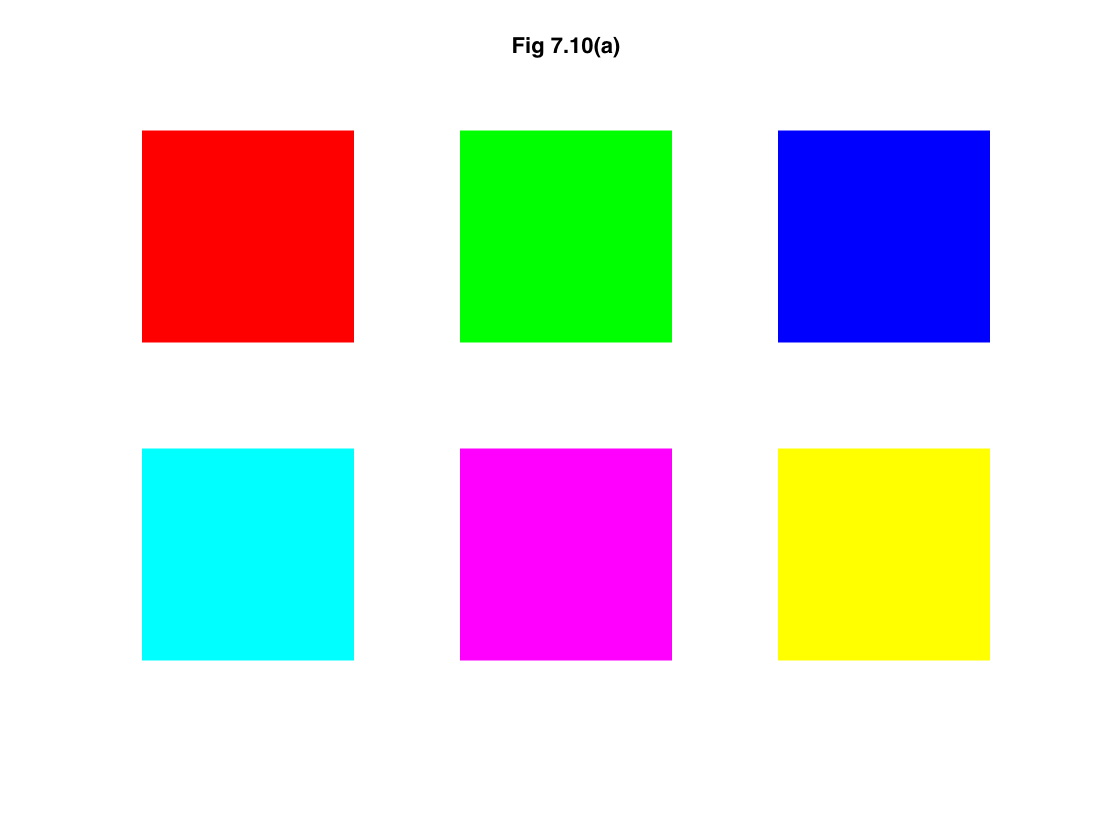

colorSwatches(colors,[2 3])
axis equal
axis off
title('Fig 7.10(a)')

Figure 7.10(a) shows the result. The second input to `colorSwatches`, the vector `[2 3]`, controls the number of rows and columns of the color swatches grid. In this case, the six colors were displayed in a grid of 2 rows and 3 columns. 

RGB colors can also be represented in MATLAB as `uint8` vectors and matrices. When `uint8` values are used, the conventional range is [0, 255] instead of [0, 1], but the colors themselves do not change. For example, 				

colors8 = im2uint8(colors)				

colors8 = 6×3 uint8 matrix
   255     0     0
     0   255     0
     0     0   255
     0   255   255
   255     0   255
   255   255     0


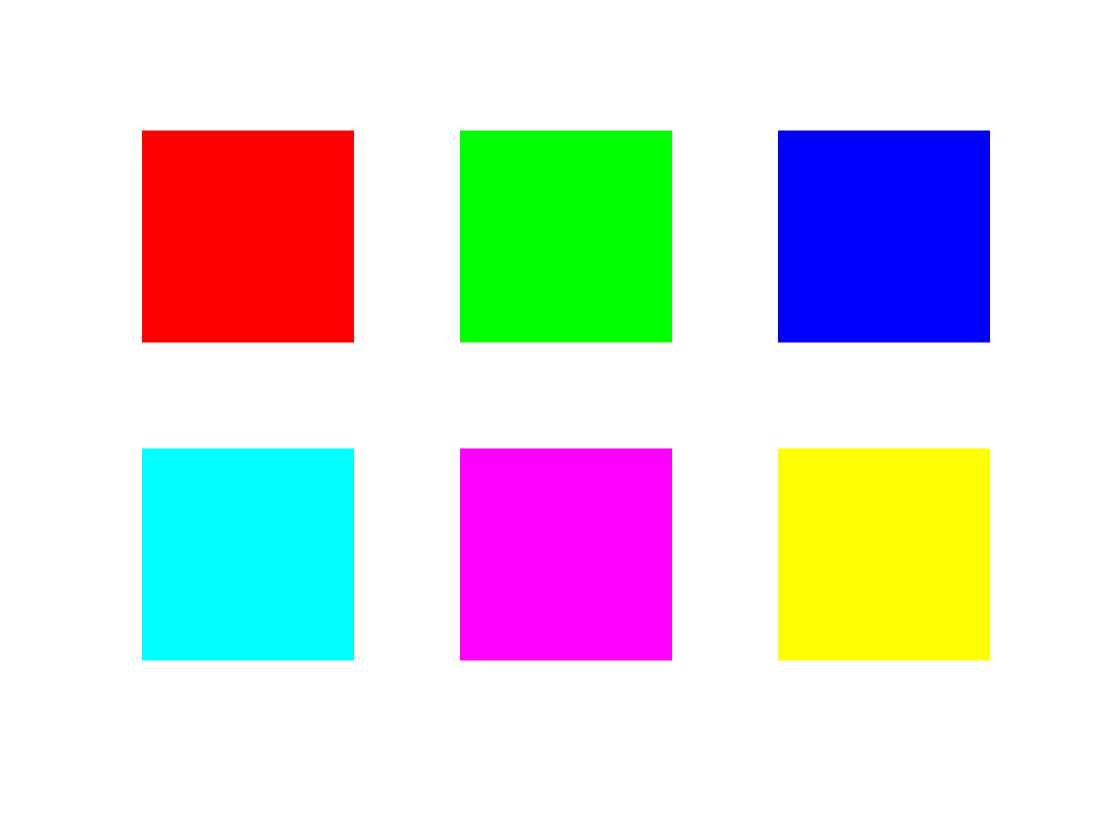

colorSwatches(colors8,[2 3])
axis equal
axis off

For another set of colors to examine, consider the colors automatically chosen by MATLAB when you plot multiple line plots together on the same axes. The function `lines` returns the colors that MATLAB uses by default for line plots. 

line_colors = lines(7)

line_colors =          0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250
    0.4940    0.1840    0.5560
    0.4660    0.6740    0.1880
    0.3010    0.7450    0.9330
    0.6350    0.0780    0.1840


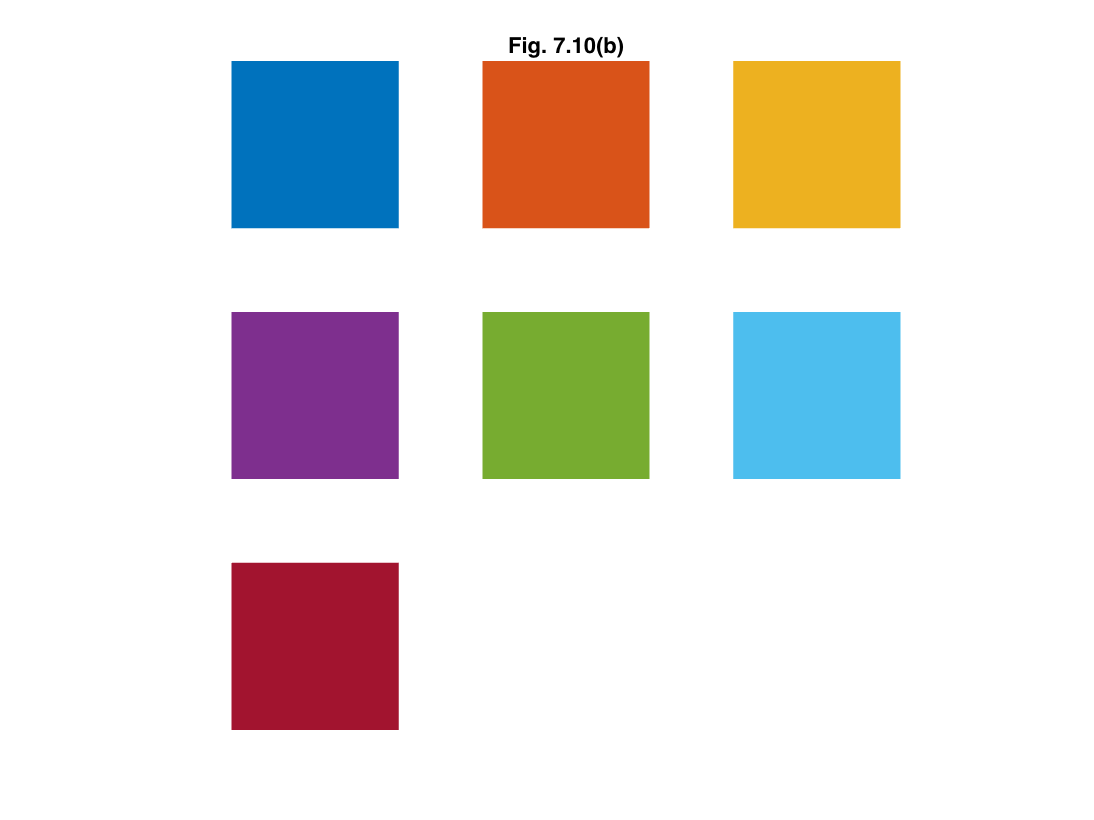

colorSwatches(line_colors,[3 3])
axis equal
axis off
title('Fig. 7.10(b)')

These MATLAB default line colors are shown in Fig. 7.10(b).

A third case illustrates using `colorSwatches` to show a large number of colors. 				

The `gap = 0` input argument is used to tell `colorSwatches` to leave no gap between each color and the `daspect` function is used to adjust the height of the color display relative to its width. To visualize the default MATLAB *parula colormap*, which has 256 colors, we type: 			

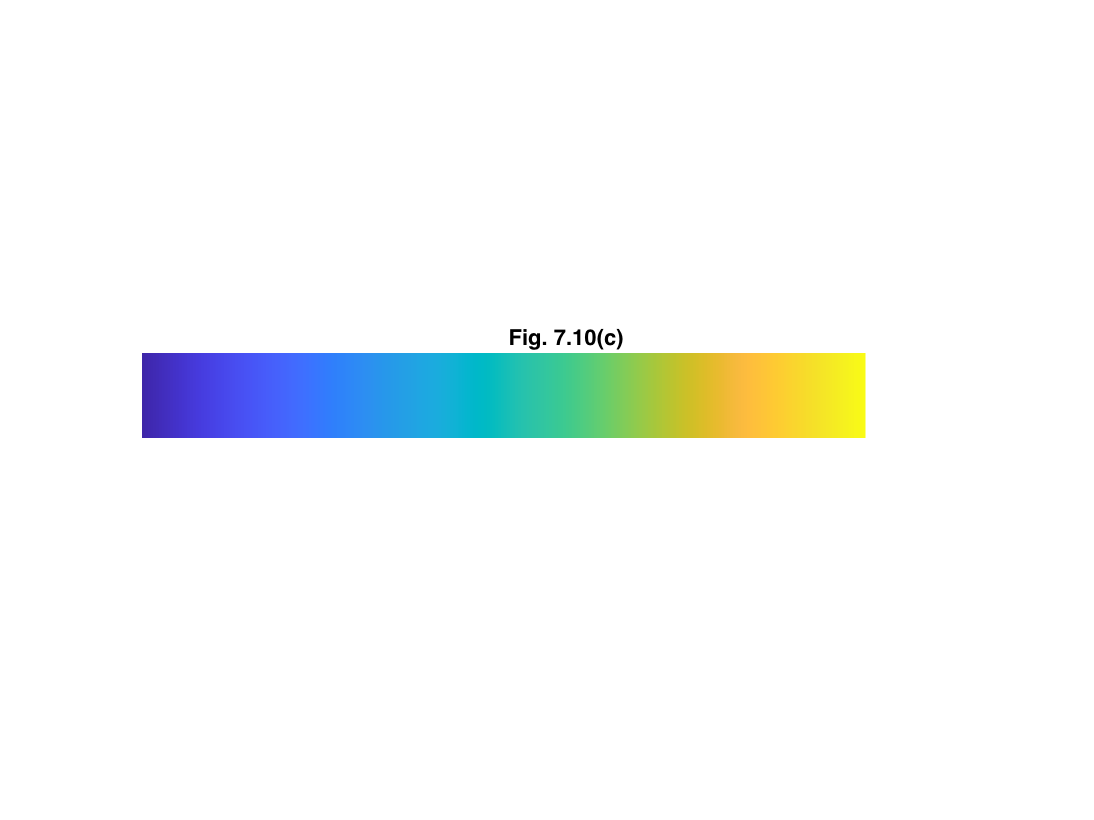

parula_colors = parula(256);
gap = 0;
colorSwatches(parula_colors,gap,[1 256])
daspect([30 1 1])
axis off
title('Fig. 7.10(c)')

The parula colors are shown in Fig. 7.10(c).